%%%Constants
mu_0 = 4*pi*1e-7;    %%%Permeability in the vacum

%%%Nominal values
%%%%%X-axis
IS501NMTB.X.L = 1.03;
IS501NMTB.X.R = 14.84;
IS501NMTB.X.a = IS501NMTB.X.L/2 ;
IS501NMTB.X.h = 0.5;
IS501NMTB.X.N = 36;
IS501NMTB.X.Lx = IS501NMTB.X.N^2*(2^(1/2)*mu_0*IS501NMTB.X.L^2)/(IS501NMTB.X.a*pi);
IS501NMTB.X.tau = IS501NMTB.X.Lx/IS501NMTB.X.R;
%%%%%Y-axis
IS501NMTB.Y.L = 1.02;
IS501NMTB.Y.a = IS501NMTB.Y.L/2;
IS501NMTB.Y.h = 0.5;
IS501NMTB.Y.N = 35;
IS501NMTB.Y.R = 7.61;
IS501NMTB.Y.Ly = IS501NMTB.Y.N^2*(2^(1/2)*mu_0*IS501NMTB.Y.L^2)/(IS501NMTB.Y.a*pi);
IS501NMTB.Y.tau = IS501NMTB.Y.Ly/IS501NMTB.Y.R;
%%%%%Z-axis
IS501NMTB.Z.L = 1.03;
IS501NMTB.Z.a = IS501NMTB.Z.L/2;
IS501NMTB.Z.h = 0.5 ;
IS501NMTB.Z.N = 20;
IS501NMTB.Z.R = 10.32;
IS501NMTB.Z.Lz = IS501NMTB.Z.N^2*(2^(1/2)*mu_0*IS501NMTB.Z.L^2)/(IS501NMTB.Z.a*pi);
IS501NMTB.Z.tau = IS501NMTB.Z.Lz/IS501NMTB.Z.R;

%%%Biot Savart law
coeff_teor = @(N,a,h) (4 * mu_0 * N * a^2) / (pi) * (1/((a^2 + (h/2)^2) * (2 * a^2 + (h/2)^2)^(1/2)));

%%%Simulation Parameters
initial_1.Lx  = IS501NMTB.X.Lx;       %%0.00208911
initial_1.Rx  = IS501NMTB.X.R;        %%14.913
initial_1.B_x = coeff_teor(IS501NMTB.X.N,IS501NMTB.X.a,IS501NMTB.X.h); %%5.38582e-05
%%%Simulation Parameters
initial_1.Ly  = IS501NMTB.Y.Ly;       %%0.00208911
initial_1.Ry  = IS501NMTB.Y.R;        %%14.913
initial_1.B_y = coeff_teor(IS501NMTB.Y.N,IS501NMTB.Y.a,IS501NMTB.Y.h); %%5.38582e-05
%%%Simulation Parameters
initial_1.Lz  = IS501NMTB.Z.Lz;       %%0.00208911
initial_1.Rz  = IS501NMTB.Z.R;        %%14.913
initial_1.B_z = coeff_teor(IS501NMTB.Z.N,IS501NMTB.Z.a,IS501NMTB.Z.h); %%5.38582e-05


initial = cell2mat(struct2cell(initial_1));

%%%1. Read data measured from the experiment
dt = 0.1;      %%Set sample time

%%% Read data measured from previous tests
fileName_x = 'data_20240114/xCoil_Epoch_2024_01_14.mat'; 
fileName_y = 'data_20240114/yCoil_Epoch_2024_01_14.mat'; 
fileName_z = 'data_20240114/zCoil_Epoch_2024_01_14.mat';
load(fileName_x); load(fileName_y); load(fileName_z);

%%% Interpretate and Clean Data
measuredData.xcoil = readProcessData(x_coil_data);
measuredData.ycoil = readProcessData(y_coil_data);
measuredData.zcoil = readProcessData(z_coil_data);
%%%Clear unused data
clear x_coil_data y_coil_data z_coil_data fileName_x fileName_y fileName_z
%%%Interpolate data to set the desired sampple time
%%% X-coil
[newDatos.x.t,newDatos.x.Bx] = setSampleTime(measuredData.xcoil.time, measuredData.xcoil.Bx,dt);
[~,newDatos.x.Ix] = setSampleTime(measuredData.xcoil.time, measuredData.xcoil.I,dt);
[~,newDatos.x.Vx] = setSampleTime(measuredData.xcoil.time,measuredData.xcoil.V,dt);
%%% Y-coil
[newDatos.y.t,newDatos.y.By] = setSampleTime(measuredData.ycoil.time, measuredData.ycoil.By,dt);
[~,newDatos.y.Iy] = setSampleTime(measuredData.ycoil.time, measuredData.ycoil.I,dt);
[~,newDatos.y.Vy] = setSampleTime(measuredData.ycoil.time,measuredData.ycoil.V,dt);
%%% Z-coil
[newDatos.z.t,newDatos.z.Bz] = setSampleTime(measuredData.zcoil.time, measuredData.zcoil.Bz,dt);
[~,newDatos.z.Iz] = setSampleTime(measuredData.zcoil.time, measuredData.zcoil.I,dt);
[~,newDatos.z.Vz] = setSampleTime(measuredData.zcoil.time,measuredData.zcoil.V,dt);

% 2. Represent the estimation data as an |iddata| object. 
y = [(newDatos.x.Bx(1:length(newDatos.y.By))-30858.71)*1E-9;
     (newDatos.y.By-(-2694.63))*1E-9;
     (newDatos.z.Bz(1:length(newDatos.y.By))-37529.93)*1E-9;
      newDatos.x.Ix(1:length(newDatos.y.By));
      newDatos.y.Iy(1:length(newDatos.y.By));
      newDatos.z.Iz(1:length(newDatos.y.By))]';
u = [newDatos.x.Vx(1:length(newDatos.y.By));
     newDatos.y.Vy;
     newDatos.z.Vz(1:length(newDatos.y.By))]';

z = iddata(y, u, dt, 'Name', 'Magnetic-testbed');

% 3. Specify input and output signal names, start time and time units. 
z.InputName = {'Vx','Vy','Vz'};
z.InputUnit =  {'V','V','V'};
z.OutputName = {'B_x', 'B_y', 'B_z', 'I_x', 'I_y', 'I_z'};
z.OutputUnit = {'T', 'T', 'T', 'A', 'A', 'A'};
z.Tstart = 0;
z.TimeUnit = 's';

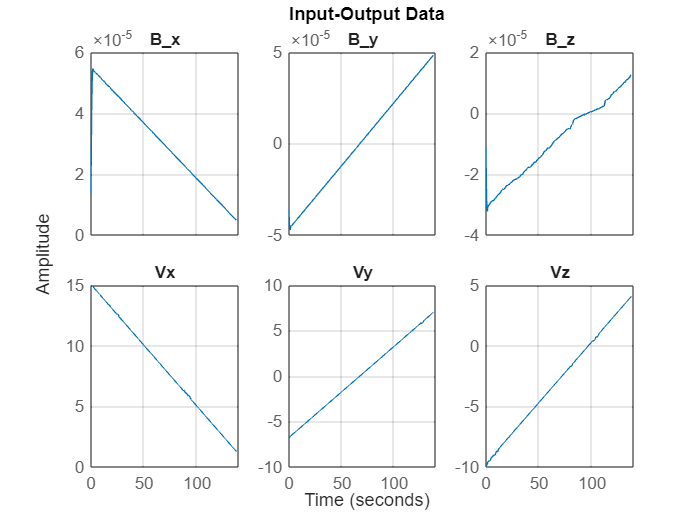

% 4. Plot the data.
%
% The data is shown in two plot windows.
figure('Name', [z.Name ': Voltage input -> Magnetic Field output']);
plot(z(:, (1:3), (1:3))); grid on;  % Plot first input-output pair (Voltage -> Angular position).

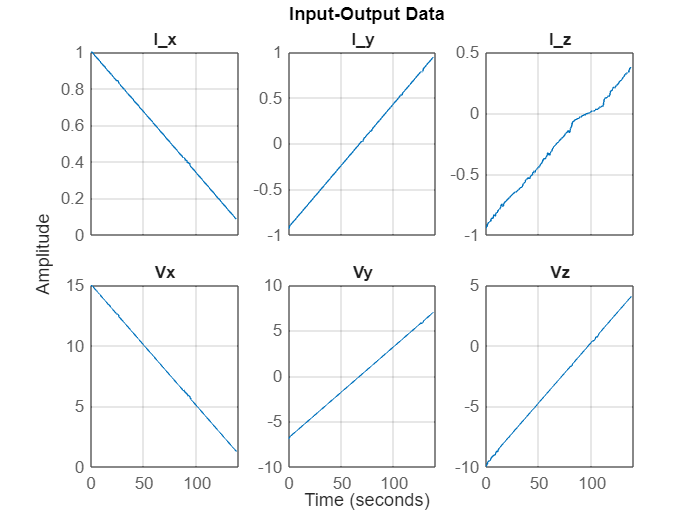

figure('Name', [z.Name ': Voltage input -> Current output']);
plot(z(:, (4:6), (1:3)));  grid on; % Plot second input-output pair (Voltage -> Angular velocity).

% 2. Represent the DC motor dynamics using an |idnlgrey| object.
%
% The model describes how the inputs generate the outputs using the state
% equation(s).
FileName      = 'is501nmtbModel';       % File describing the model structure.
Order         = [6 3 3];           % Model orders [ny nu nx].
%Parameters    = [1; 0.28];        % Initial parameters. Np = 2.
Parameters    = [initial;0;0;0]';          % Initial parameters. Np = 12.
InitialStates = [0;0;0];            % Initial initial states.
%InitialStates = [0; 0];            % Initial initial states.
Ts            = 0;                 % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts, ...
                'Name', 'Magnetic-testbed');

% 3. Specify input and output names, and units.
set(nlgr, 'InputName', {'Vx','Vy','Vz'}, 'InputUnit', {'V','V','V'},               ...
          'OutputName', {'B_x', 'B_y', 'B_z', 'I_x', 'I_y', 'I_z'}, ...
          'OutputUnit', {'T', 'T', 'T', 'A', 'A', 'A'},                         ...
          'TimeUnit', 's');

%4. Specify names and units of the initial states and parameters.
nlgr = setinit(nlgr, 'Name',  {'I_x', 'I_y', 'I_z'});
nlgr = setinit(nlgr, 'Unit',  {'A', 'A', 'A'});
nlgr = setpar(nlgr, 'Name', {'Lxx','Rx','B_1','Lyy','Ry','B_2','Lzz','Rz','B_3','Lxy','Lxz','Lzy'});
nlgr = setpar(nlgr, 'Unit', {'H','ohm','T/A','H','ohm','T/A','H','ohm','T/A','H','H','H'});

% You can also use |setinit| and |setpar| to assign values, minima, maxima,
% and estimation status for all initial states or parameters
% simultaneously.
%
% 5. View the initial model.
%
% a. Get basic information about the model.
%
% The DC-motor has 2 (initial) states and 2 model parameters.
size(nlgr)

Nonlinear grey-box model with 6 outputs, 3 inputs, 3 states and 12 parameters (12 free).


% b. View the initial states and parameters.
%
% Both the initial states and parameters are structure arrays. The fields
% specify the properties of an individual initial state or parameter. Type
% |help idnlgrey.InitialStates| and |help idnlgrey.Parameters| for
% more information.
nlgr.Parameters(1).Minimum = 0; nlgr.Parameters(1).Fixed = 0; nlgr.Parameters(1)

ans = struct with fields:
       Name: 'Lxx'
       Unit: 'H'
      Value: 0.0015
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(2).Minimum = 0; nlgr.Parameters(2).Fixed = 0; nlgr.Parameters(2)

ans = struct with fields:
       Name: 'Rx'
       Unit: 'ohm'
      Value: 14.8400
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(3).Minimum = 0; nlgr.Parameters(3).Fixed = 0; nlgr.Parameters(3)

ans = struct with fields:
       Name: 'B_1'
       Unit: 'T/A'
      Value: 6.0537e-05
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(4).Minimum = 0; nlgr.Parameters(4).Fixed = 0; nlgr.Parameters(4)

ans = struct with fields:
       Name: 'Lyy'
       Unit: 'H'
      Value: 0.0014
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(5).Minimum = 0; nlgr.Parameters(5).Fixed = 0; nlgr.Parameters(5)

ans = struct with fields:
       Name: 'Ry'
       Unit: 'ohm'
      Value: 7.6100
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(6).Minimum = 0; nlgr.Parameters(6).Fixed = 0; nlgr.Parameters(6)

ans = struct with fields:
       Name: 'B_2'
       Unit: 'T/A'
      Value: 5.9148e-05
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(7).Minimum = 0; nlgr.Parameters(7).Fixed = 0; nlgr.Parameters(7)

ans = struct with fields:
       Name: 'Lzz'
       Unit: 'H'
      Value: 4.6612e-04
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(8).Minimum = 0; nlgr.Parameters(8).Fixed = 0; nlgr.Parameters(8)

ans = struct with fields:
       Name: 'Rz'
       Unit: 'ohm'
      Value: 10.3200
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(9).Minimum = 0; nlgr.Parameters(9).Fixed = 0; nlgr.Parameters(9)

ans = struct with fields:
       Name: 'B_3'
       Unit: 'T/A'
      Value: 3.3631e-05
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(10).Fixed  = true;
nlgr.Parameters(11).Fixed  = true;
nlgr.Parameters(12).Fixed  = true;

%%
%
% c. Retrieve information for all initial states or model parameters in one
% call.
% 
% For example, obtain information on initial states that are fixed (not
% estimated) and the minima of all model parameters.
getinit(nlgr, 'Fixed')

ans = 3×1 cell array
    {[1]}
    {[1]}
    {[1]}


getpar(nlgr, 'Min')

ans = 12×1 cell array
    {[   0]}
    {[   0]}
    {[   0]}
    {[   0]}
    {[   0]}
    {[   0]}
    {[   0]}
    {[   0]}
    {[   0]}
    {[-Inf]}
    {[-Inf]}
    {[-Inf]}


%
% d. Obtain basic information about the object:
nlgr

nlgr =

Continuous-time nonlinear grey-box model defined by 'is501nmtbModel' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p12)
    y(t) = H(t, u(t), x(t), p1, ..., p12) + e(t)

 with 3 input(s), 3 state(s), 6 output(s), and 9 free parameter(s) (out of 12).

Name: Magnetic-testbed

Status:                                                         
Created by direct construction or transformation. Not estimated.

Model Properties


%%
% Use |get| to obtain more information about the model properties. The
% |idnlgrey| object shares many properties of parametric linear model
% objects.
get(nlgr)

             FileName: 'is501nmtbModel'
                Order: [1×1 struct]
           Parameters: [12×1 struct]
        InitialStates: [3×1 struct]
         FileArgument: {}
    SimulationOptions: [1×1 struct]
         TimeVariable: 't'
        NoiseVariance: [6×6 double]
            InputName: {3×1 cell}
            InputUnit: {3×1 cell}
           InputGroup: [1×1 struct]
           OutputName: {6×1 cell}
           OutputUnit: {6×1 cell}
          OutputGroup: [1×1 struct]
                Notes: [0×1 string]
             UserData: []
                 Name: 'Magnetic-testbed'
                   Ts: 0
             TimeUnit: 'seconds'
               Report: [1×1 idresults.nlgreyest]



%% Performance Evaluation of the Initial DC-Motor Model
%
% Before estimating the parameters |tau| and |k|, simulate the output of
% the system with the parameter guesses using the default differential
% equation solver (a Runge-Kutta 45 solver with adaptive step length
% adjustment). The simulation options are specified using the
% "SimulationOptions" model property.
%
% 1. Set the absolute and relative error tolerances to
% small values (|1e-6| and |1e-5|, respectively).
nlgr.SimulationOptions.AbsTol = 1e-6;
nlgr.SimulationOptions.RelTol = 1e-5;


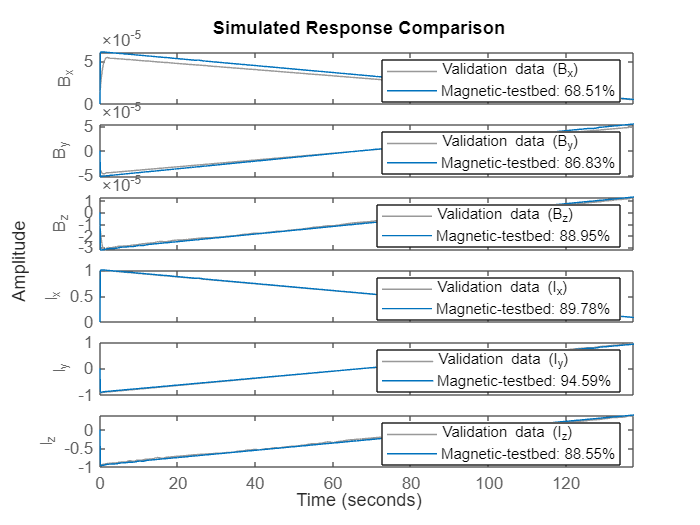

%%
%
% 2. Compare the simulated output with the measured data.
%
% |compare| displays both measured and simulated outputs of one or more
% models, whereas |predict|, called with the same input arguments, displays
% the simulated outputs.
%
% The simulated and measured outputs are shown in a plot window.
compare(z, nlgr);

%% Parameter Estimation
% Estimate the parameters and initial states using |nlgreyest|, which is a
% prediction error minimization method for nonlinear grey box models. The
% estimation options, such as the choice of estimation progress display,
% are specified using the "nlgreyestOptions" option set.
nlgr = setinit(nlgr, 'Fixed', {false,false,false}); % Estimate the initial states.
opt = nlgreyestOptions('Display', 'on');
nlgr = nlgreyest(z, nlgr, opt);


function coil = readProcessData(coil_data)
    %%%Interpretate data
    time = coil_data(1,:); Bx = coil_data(2,:); 
    By   = coil_data(3,:); Bz = coil_data(4,:);
    V    = coil_data(5,:); I  = coil_data(6,:);
    %%%Clean data
    coil.time = time(~isnan(time));
    coil.Bx = Bx(~isnan(Bx)); 
    coil.By = By(~isnan(By)); 
    coil.Bz = Bz(~isnan(Bz));
    coil.V  = V(~isnan(V)); 
    coil.I  = I(~isnan(I));
end

function [ t_uniform, x_uniform] = setSampleTime(tout,data,t_sample)
    %%% Interpolation to have uniform sampling
    %temp = diff(tout);               %%Temporal time
    %t_sample = mean(temp(1:end-1));                             %%Get sample time
    t_uniform = tout(1):t_sample:tout(end); %%Define a uniform time vector
    %%% Start interpolation
    x_uniform = interp1(tout, data, t_uniform, 'spline');  % Interpolación
end
